# Data distribution of the capacity factors

Description: This algorithm plot the data distribution of the capacity factors for the different sources 

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 10/2021

clc
clear
close all

run CF_Calculation.mlx

Solar_CF=CF_Sol(:);
Wind_CF=CF_Win(:);
Hydro_CF=CF_Hyd(:);
Geothermal_CF=CF_Geo(:);
Nuclear_CF=CF_Nuc(:);
Biofuels_CF=CF_Bio(:);
Fossil_CF=CF_Fos(:);
clearvars -except Solar_CF Wind_CF Hydro_CF Geothermal_CF Nuclear_CF Biofuels_CF Fossil_CF

Print='F'

Print = 'F'

% Colormap
Color=[85,200,60        % Biomass   
      55,55,55          % Fossil
      202,0,32          % Geothermal
      33,102,172        % Hydro
      128,115,172       % Nuclear
      255,199,44        % Solar  
      146,197,222]/255; % Wind 


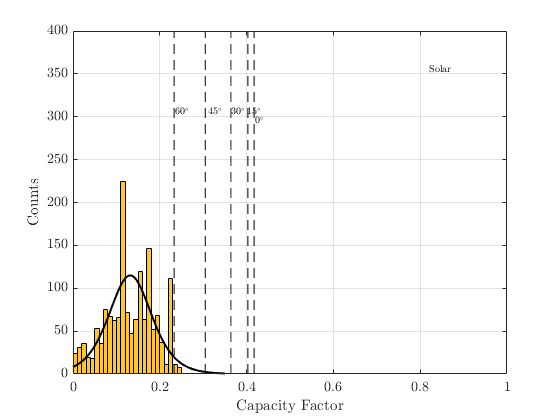

CFS_M=[0.417245370370370	0.402874228395062	0.363908179012346	0.304687500000000	0.233121141975309];
figure
h=histfit(Solar_CF,25,'logistic');
h(1).FaceColor=Color(6,:);
h(2).Color='k';
hold on
for n=1:5
    plot([CFS_M(n) CFS_M(n) ],[0 400],'--k')
end
text(0.235,305,'$\mathrm{60^\circ}$','Interpreter','latex')
text(0.31,305,'$\mathrm{45^\circ}$','Interpreter','latex')
text(0.365,305,'$\mathrm{30^\circ}$','Interpreter','latex')
text(0.402,305,'$\mathrm{15^\circ}$','Interpreter','latex')
text(0.42,295,'$\mathrm{0^\circ}$','Interpreter','latex')
xlabel('Capacity Factor','Interpreter','latex')
ylabel('Counts','Interpreter','latex')
grid on
xlim([0 1])
text(0.82,355,'Solar','Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-dpng','-r400','Hist_Sol.png')
end

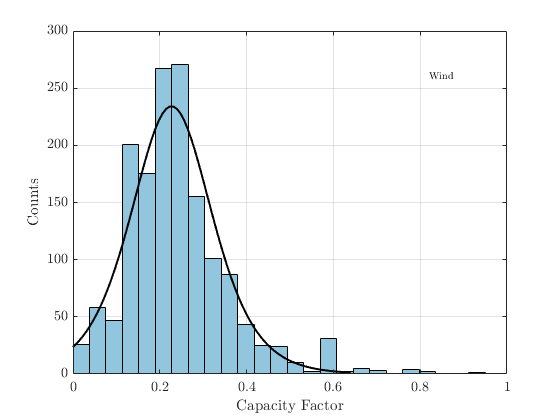


figure
h=histfit(Wind_CF,25,'logistic');
h(1).FaceColor=Color(7,:);
h(2).Color='k';
grid on
xlim([0 1])
text(0.82,260,'Wind','Interpreter','latex')
ylabel('Counts','Interpreter','latex')
xlabel('Capacity Factor','Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-dpng','-r400','Hist_Win.png')
end

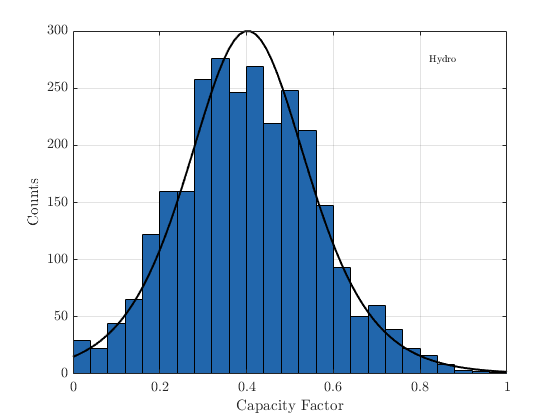


figure
h=histfit(Hydro_CF,25,'logistic');
h(1).FaceColor=Color(4,:);
h(2).Color='k';
grid on
xlim([0 1])
text(0.82,275,'Hydro','Interpreter','latex')
ylabel('Counts','Interpreter','latex')
xlabel('Capacity Factor','Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-dpng','-r400','Hist_Hyd.png')
end

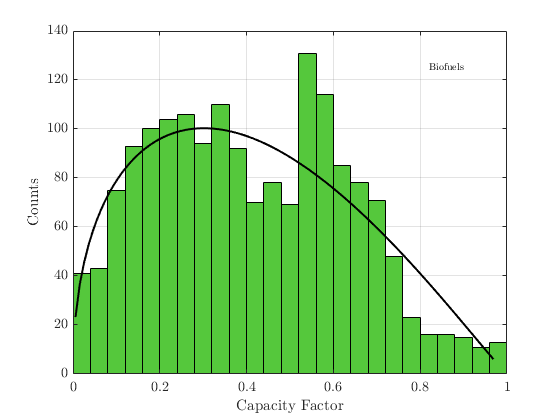

figure
h=histfit(Biofuels_CF,25,'beta');
h(1).FaceColor=Color(1,:);
h(2).Color='k';
grid on
xlim([0 1])
text(0.82,125,'Biofuels','Interpreter','latex')
ylabel('Counts','Interpreter','latex')
xlabel('Capacity Factor','Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-dpng','-r400','Hist_Bio.png')
end

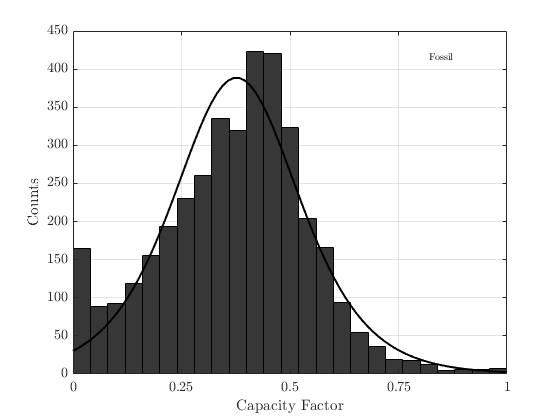

figure
h=histfit(Fossil_CF,25,'logistic');
h(1).FaceColor=Color(2,:);
h(2).Color='k';
grid on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.82,415,'Fossil','Interpreter','latex')
ylabel('Counts','Interpreter','latex')
xlabel('Capacity Factor','Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

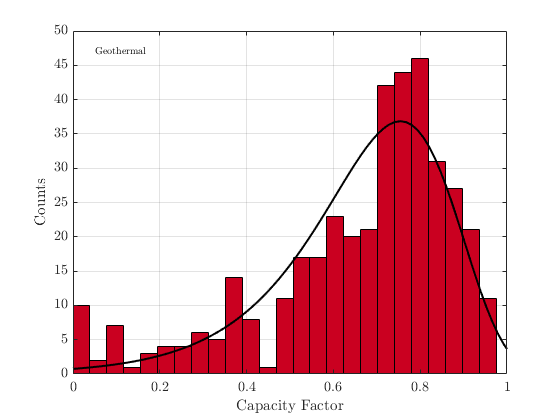

if Print=='T'
    print('-dpng','-r400','Hist_Fos.png')
end
figure
h=histfit(Geothermal_CF,25,'extreme value');
h(1).FaceColor=Color(3,:);
h(2).Color='k';
grid on
xlim([0 1])
text(0.05,47,'Geothermal','Interpreter','latex')
ylabel('Counts','Interpreter','latex')
xlabel('Capacity Factor','Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-dpng','-r400','Hist_Geo.png')
end

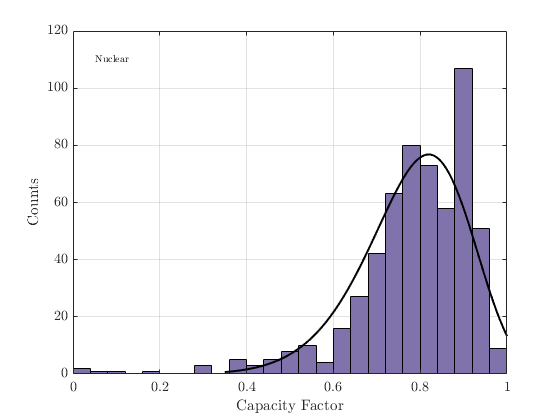

figure
h=histfit(Nuclear_CF,25,'weibull');
h(1).FaceColor=Color(5,:);
h(2).Color='k';
grid on
xlim([0 1])
text(0.05,110,'Nuclear','Interpreter','latex')
ylabel('Counts','Interpreter','latex')
xlabel('Capacity Factor','Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-dpng','-r400','Hist_Nuc.png')
end

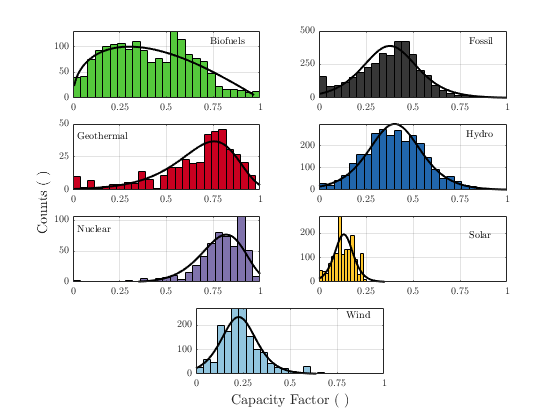

fig=figure;

h(1) = subplot(4,2,1);
hh=histfit(Biofuels_CF,25,'beta');
hh(1).FaceColor=Color(1,:);
hh(2).Color='k';
grid on
box on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.73,110,'Biofuels','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(2) = subplot(4,2,2);
hh=histfit(Fossil_CF,25,'logistic');
hh(1).FaceColor=Color(2,:);
hh(2).Color='k';
grid on
box on
yticks([0 250 500])
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.8,420,'Fossil','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(3) = subplot(4,2,3);
hh=histfit(Geothermal_CF,25,'extreme value');
hh(1).FaceColor=Color(3,:);
hh(2).Color='k';
grid on
box on
yticks([0 25 50])
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.02,40,'Geothermal','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(4) = subplot(4,2,4);
hh=histfit(Hydro_CF,25,'logistic');
hh(1).FaceColor=Color(4,:);
hh(2).Color='k';
grid on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.78,250,'Hydro','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(5) = subplot(4,2,5);
hh=histfit(Nuclear_CF,25,'weibull');
hh(1).FaceColor=Color(5,:);
hh(2).Color='k';
grid on
box on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.02,85,'Nuclear','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(6) = subplot(4,2,6);
hh=histfit(Solar_CF,15,'logistic');
hh(1).FaceColor=Color(6,:);
hh(2).Color='k';
hold on
grid on
box on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.8,190,'Solar','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(7) = subplot(4,2,7);
hh=histfit(Wind_CF,25,'logistic');
hh(1).FaceColor=Color(7,:);
hh(2).Color='k';
grid on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.8,240,'Wind','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

pos = get(h,'Position');
new = mean(cellfun(@(v)v(1),pos(1:2)));
 set(h(7),'Position',[new,pos{end}(2:end)])

% Give common xlabel, ylabel and title to your figure
han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Counts ( )','Interpreter','latex','FontSize',14);
xlabel(han,'Capacity Factor ( )','Interpreter','latex','FontSize',14);


if Print=='T'
    print('-dpng','-r400','Hist_All.png')
end

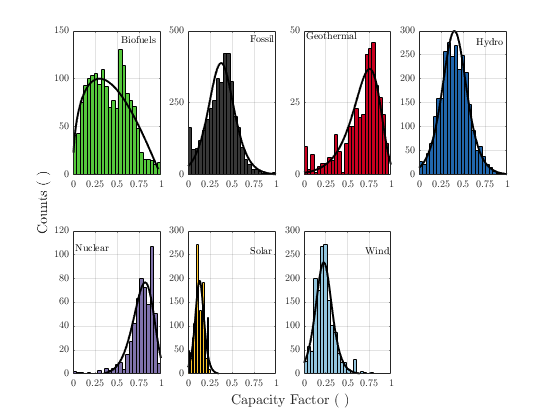


fig=figure;

h(1) = subplot(2,4,1);
hh=histfit(Biofuels_CF,25,'beta');
hh(1).FaceColor=Color(1,:);
hh(2).Color='k';
grid on
box on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.55,140,'Biofuels','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(2) = subplot(2,4,2);
hh=histfit(Fossil_CF,25,'logistic');
hh(1).FaceColor=Color(2,:);
hh(2).Color='k';
grid on
box on
yticks([0 250 500])
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.7,470,'Fossil','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(3) = subplot(2,4,3);
hh=histfit(Geothermal_CF,25,'extreme value');
hh(1).FaceColor=Color(3,:);
hh(2).Color='k';
grid on
box on
yticks([0 25 50])
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.02,48,'Geothermal','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(4) = subplot(2,4,4);
hh=histfit(Hydro_CF,25,'logistic');
hh(1).FaceColor=Color(4,:);
hh(2).Color='k';
grid on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.65,275,'Hydro','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(5) = subplot(2,4,5);
hh=histfit(Nuclear_CF,25,'weibull');
hh(1).FaceColor=Color(5,:);
hh(2).Color='k';
grid on
box on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.02,105,'Nuclear','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(6) = subplot(2,4,6);
hh=histfit(Solar_CF,15,'logistic');
hh(1).FaceColor=Color(6,:);
hh(2).Color='k';
hold on
grid on
box on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.7,255,'Solar','Interpreter','latex')
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

h(7) = subplot(2,4,7);
hh=histfit(Wind_CF,25,'logistic');
hh(1).FaceColor=Color(7,:);
hh(2).Color='k';
grid on
xlim([0 1])
xticks([0 0.25 0.5 0.75 1])
text(0.7,255,'Wind','Interpreter','latex')
% set(gca,'Position',[100 100 1200 1000])
set(gca,'Fontsize',10,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

pos = get(h,'Position');
new = mean(cellfun(@(v)v(1),pos(1:2)));
% set(h(7),'Position',[new,pos{end}(2:end)])

% Give common xlabel, ylabel and title to your figure
han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Counts ( )','Interpreter','latex','FontSize',14);
xlabel(han,'Capacity Factor ( )','Interpreter','latex','FontSize',14);


if Print=='T'
%     print('-dpng','-r400','Hist_All.png')
end
